f=imread('radiograph1.jpg'); %Carga el archivo siempre
%                            y cuando esté en la misma carpeta
imshow(f)



f=f(:,:,1); %%Tomar solo 1 canal 
imshow(f);



f=double(f)/255; %%
imshow(f); 



f=imresize(f,0.25); %Redimenciona el tamaño a 1/4 de la original
figure(1);
subplot(2,2,1);
imshow(f,[]);
subplot(2,2,2);
mesh(f) %Gráfica 3D del espectro



h=10*fspecial('gaussian',7,2); %filtro gaussiano

subplot(2,2,3);
imshow(h,[]);
mesh(h); 

sum(sum(h));

g = conv2(f,h,'same'); %Calcula un promedio en el espectro

subplot(2,2,4);
%mesh(g); 
imshow(g,[]);



% F=fft2(f,sz(1),sz(2)); %transformada de Fourier
% subplot(2,2,4);
% imshow(fftshift(log(abs(F))),[]) 



sz=size(f); %calcula el tamaño de la foto original
f=zeros(sz(1)); %crea una matriz de 0s del tamaño anterior
f(int16(sz(1)/2),int16(sz(2)/2))=1;%ponemos un valor en medio de la imagen igual a 1
f(int16(sz(1)/2),int16(sz(2)/3))=1;
f(int16(sz(1)/3),int16(sz(2)/2))=1;
subplot(2,2,2)
imshow(f,[]);

h=fspecial('gaussian',7,2); %Campana de gauss de 7 pixeles
subplot(2,2,3);
mesh(h);

g = conv2(f,h,'same'); %Convolución usando la función gaussiana
subplot(2,2,4)
%imshow(g,[]);
mesh(g);




for(x=1:sz(1))%% funciones senoidales
    for (y=1:sz(2))
        f(y,x)=sin(y*0.5)*sin(x*0.5); 
end
end
subplot(2,2,1);
imshow(f,[]);


F=fft2(f,sz(1),sz(2));
subplot(2,2,2);
imshow(fftshift(log(abs(F))),[])

subplot(2,2,3);
imshow(fftshift((abs(F))),[])


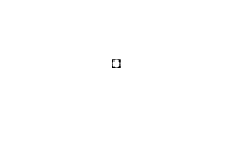


psf=fspecial('disk',3);
imshow(psf,[]);

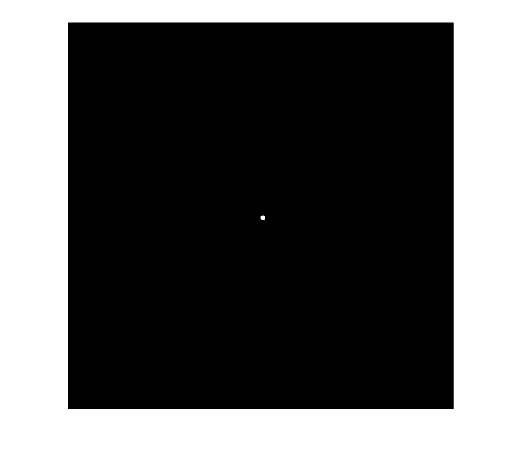

f=zeros(512);%Tamaño de img de 512
f(256:256+6,256:256+6)=psf;%tamaño de 7 pixeles
imshow(f,[]);

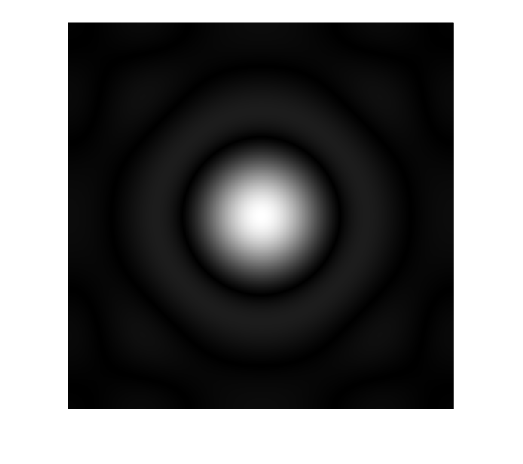

MTF=abs(fft2(f));
figure(2);
imshow(fftshift(MTF),[]);

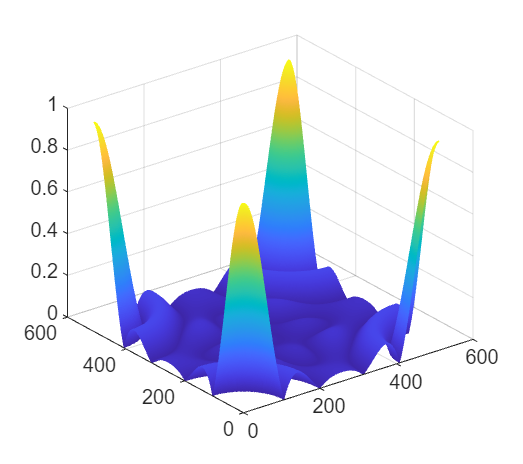

figure(3);
mesh(MTF);

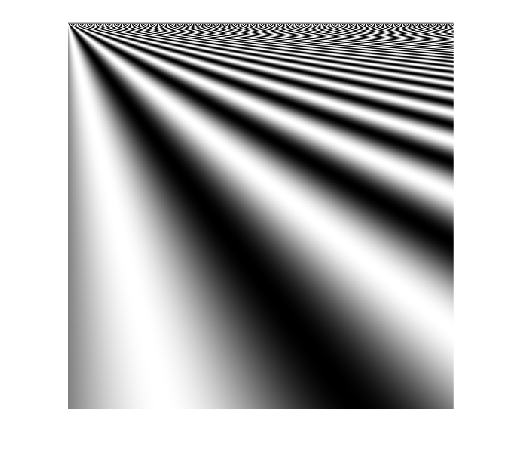

psf=fspecial('disk',10);
sines=zeros (512);
for (x=1:512)
    for (y=1:512)
        sines (y,x)=sin(x*(pi/y*2));
    end
end 
figure (4)
imshow(sines,[-1,1]);

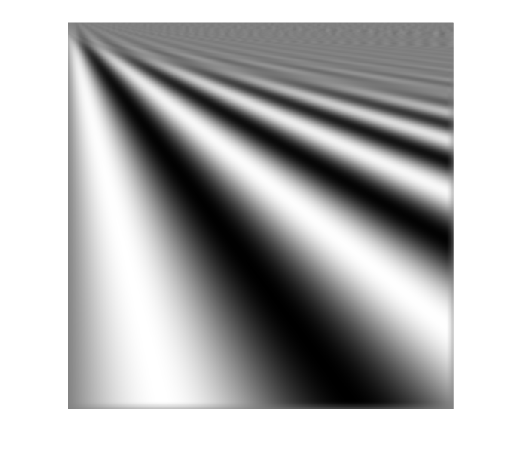

g=conv2(sines, psf,'same');
figure(5);
imshow(g,[-1,1]);